# Solve Stiff Transistor Differential Algebraic Equation

This example shows how to solve a stiff differential algebraic equation (DAE) that describes an electrical circuit [1]. The one-transistor amplifier problem coded in the example file [amp1dae.m](matlab:edit('amp1dae.m')) can be rewritten in semi-explicit form, but this example solves it in its original form $M u' = \phi(u)$. The problem includes a constant, singular mass matrix $M$. 

The transistor amplifier circuit contains six resistors, three capacitors, and a transistor.

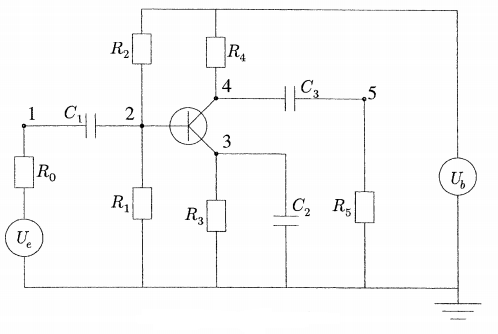

- The initial voltage signal is $U_e(t)=0.4 \sin\left( 200 \pi t \right)$.

- The operating voltage is $U_b =6$.

- The voltages at the nodes are given by $U_i \left(t\right)\;\;\left(i=1,2,3,4,5\right)$.

- The values of the resistors $R_i \;\;\left(i=1,2,3,4,5,6\right)$ are constant, and the current through each resistor satisfies $I=U/R$.

- The values of the capacitors $C_i \;\;\left(i=1,2,3\right)$ are constant, and the current through each capacitor satisfies $I=C\cdot \textrm{dU}/\textrm{dt}$.

The goal is to solve for the output voltage through node 5, $U_5 \left(t\right)$.

To solve this equation in MATLAB®, you can use an `ode` object and set properties of the object to define the equations, mass matrix, and initial conditions. Then, use the `solve` method to simulate the system over time. You can either include the required functions as functions within a script (as done here), or save them as separate, named files in a directory on the MATLAB path.

## Code Mass Matrix

Using Kirchoff's law to equalize the current through each node (1 through 5), you can obtain a system of five equations describing the circuit:


$$\begin{array}{l}
\textrm{node}\;1:\;\;\frac{U_e \left(t\right)}{R_0 }-\frac{U_1 }{R_0 }+C_1 \left({U_2 }^{\prime } -{U_1 }^{\prime } \right)=0,\\
\textrm{node}\;2:\;\;\frac{U_b }{R_2 }-U_2 \left(\frac{1}{R_1 }+\frac{1}{R_2 }\right)+C_1 \left({U_1 }^{\prime } -{U_2 }^{\prime } \right)-0\ldotp 01f\left(U_2 -U_3 \right)=0,\\
\textrm{node}\;3:\;\;f\left(U_2 -U_3 \right)-\frac{U_3 }{R_3 }-C_2 {U_3 }^{\prime } =0,\\
\textrm{node}\;4:\;\;\frac{U_b }{R_4 }-\frac{U_4 }{R_4 }+C_3 \left({U_5 }^{\prime } -{U_4 }^{\prime } \right)-0\ldotp 99f\left(U_2 -U_3 \right)=0,\\
\textrm{node}\;5:\;\;-\frac{U_5 }{R_5 }+C_3 \left({U_4 }^{\prime } -{U_5 }^{\prime } \right)=0\ldotp 
\end{array}$$


The mass matrix of this system, found by collecting the derivative terms on the left side of the equations, has the form


$$ M = \left( \begin{array}{ccccc} -c_1 & c_1 & 0 & 0 & 0\\ c_1 & -c_1 &
0 & 0 & 0\\ 0 & 0 & -c_2 & 0 & 0\\ 0 & 0 & 0 & -c_3 & c_3\\ 0 & 0 & 0 &
c_3 & -c_3 \end{array} \right),$$


where $c_k = k \times 10^{-6}$ for $k=1,2,3$.

Create a mass matrix with the appropriate constants $c_k$, and then create an `odeMassMatrix` object to store the mass matrix. Even though it is apparent that the mass matrix is singular, leave the `Singular` property at its default value of `"maybe"` to test the automatic detection of a DAE problem by the solver.

c = 1e-6 * (1:3);
M = zeros(5,5);
M(1,1) = -c(1);
M(1,2) =  c(1);
M(2,1) =  c(1);
M(2,2) = -c(1);
M(3,3) = -c(2);
M(4,4) = -c(3);
M(4,5) =  c(3);
M(5,4) =  c(3);
M(5,5) = -c(3);
Mass = odeMassMatrix(MassMatrix=M);

## Code Equations

The function `transampdae` contains the system of equations for this example. The function defines values for all of the voltages and constant parameters. The derivatives gathered on the left side of the equations are coded in the mass matrix, and `transampdae` codes the right side of the equations.

function dudt = transampdae(t,u)
% Define voltages and parameters
Ue = @(t) 0.4*sinpi(200*t);
Ub = 6;
R0 = 1000;
R15 = 9000;
alpha = 0.99;
beta = 1e-6;
Uf = 0.026;

% Define system of equations
f23 = beta*(exp((u(2) - u(3))/Uf) - 1);
dudt = [ -(Ue(t) - u(1))/R0
    -(Ub/R15 - u(2)*2/R15 - (1-alpha)*f23)
    -(f23 - u(3)/R15)
    -((Ub - u(4))/R15 - alpha*f23)
    (u(5)/R15) ];
end

## Code Initial Conditions

Set the initial conditions. This example uses the consistent initial conditions for the current through each node computed in [1].

Ub = 6;
u0(1) = 0;
u0(2) = Ub/2;
u0(3) = Ub/2;
u0(4) = Ub;
u0(5) = 0;

## Solve System of Equations

Create an `ode` object to describe the problem, setting the values of the `ODEFcn`, `MassMatrix`, and `InitialValue` properties. Also, select the `ode23t` solver to solve the problem.

F = ode(ODEFcn=@transampdae,MassMatrix=Mass,InitialValue=u0,Solver="ode23t")

Solve the DAE system over the time interval `[0 0.05]` using the `solve` method. 

S = solve(F,0,0.05);
t = S.Time;
u = S.Solution;

## Plot Results

Plot the initial voltage $U_e(t)$ and output voltage through node 5, $U_5(t)$.

Ue = @(t) 0.4*sinpi(200*t);
plot(t,Ue(t),"o",t,u(5,:),".")
axis([0 0.05 -3 2]);
legend("Input Voltage U_e(t)","Output Voltage U_5(t)",Location="NorthWest");
title("One Transistor Amplifier DAE Problem Solved by ODE23T");
xlabel("t");

## References

[1] Hairer, E., and Gerhard Wanner. *Solving Ordinary Differential Equations II: Stiff and Differential-Algebraic Problems*. Springer Berlin Heidelberg, 1991, p. 377.

*Copyright 2020 The MathWorks, Inc.*